t = 0:0.02:10;   %vetor of time for output, 0 to 10 at 0.02 increments


m = 5;      %value of mass (kg)
L = 0.5;      %value of length (m)
g = 9.81    %value of gravity acceleration (m/sec^2)

g = 9.8100


omega = g / L;   %use natural cutoff frequency

s = tf('s');    %set up transfer function input mode
sys = (1/(m*L^2))/(s^2 + omega)   %transfer function

sys =
 
      0.8
  -----------
  s^2 + 19.62
 
Continuous-time transfer function.



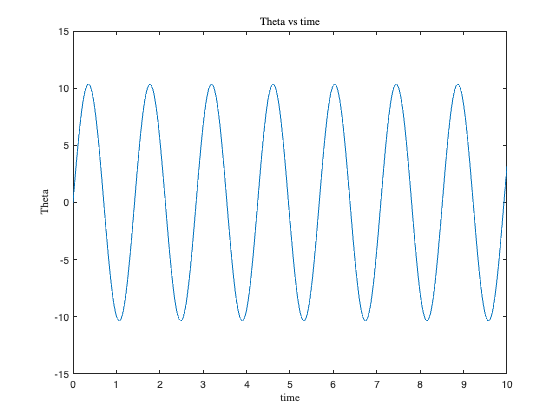


y = impulse(sys,t);    %impulse response input at t = 0

Rad2Deg = 57.3;     %converts rads to degrees

plot(t,Rad2Deg * y)     %plots y (remember y is in theta!
title ('Theta vs time')
xlabel ('time')
ylabel ('Theta')


sys = tf([1], [1, omega]); %Calculate the transfer function for a specific frequency
sys2 =tf([1], [1, omega * 10000]) %Calculate the transfer function for a higher frequency

sys2 =
 
      1
  ----------
  s + 196200
 
Continuous-time transfer function.



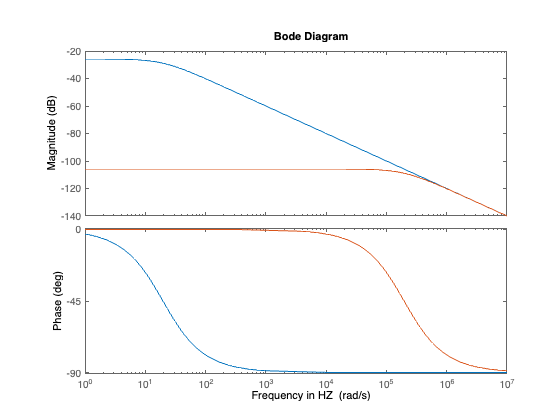


bode(sys, sys2); %plot the Bode Function
xlabel ('Frequency in HZ')